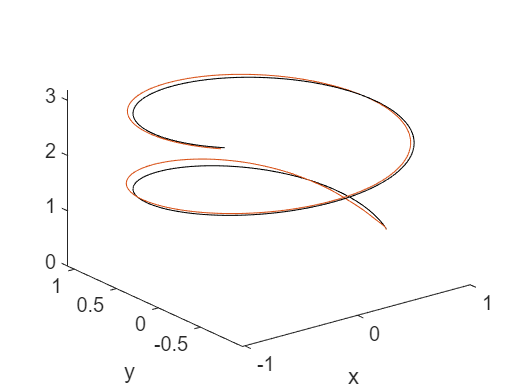

figure;
plot3(out.simout.signals.values(:,13),out.simout.signals.values(:,14),out.simout.signals.values(:,15),'-k');
xlabel('x');
ylabel('y');
hold on;
plot3(out.simout.signals.values(:,1),out.simout.signals.values(:,2),out.simout.signals.values(:,3))

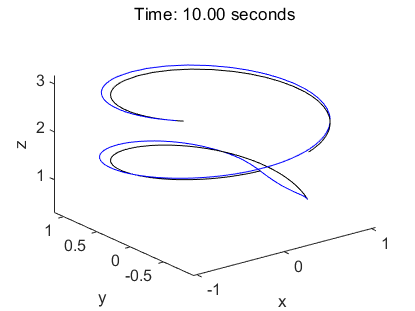

figure;
% 设置目标轨迹
plot3(out.simout.signals.values(:,13), out.simout.signals.values(:,14), out.simout.signals.values(:,15), '-k');
xlabel('x');
ylabel('y');
zlabel('z');
hold on;

% 设置实际轨迹的初始部分
h = plot3(out.simout.signals.values(1,1), out.simout.signals.values(1,2), out.simout.signals.values(1,3), 'b'); % 初始点

% 设置图形范围（根据实际数据调整）
xlim([min(out.simout.signals.values(:,1)) max(out.simout.signals.values(:,1))]);
ylim([min(out.simout.signals.values(:,2)) max(out.simout.signals.values(:,2))]);
zlim([min(out.simout.signals.values(:,3)) max(out.simout.signals.values(:,3))]);

% 动态展示无人机轨迹
for i = 1:length(out.simout.time)
    % 更新实际轨迹（到第i个时刻）
    set(h, 'XData', out.simout.signals.values(1:i, 1));
    set(h, 'YData', out.simout.signals.values(1:i, 2));
    set(h, 'ZData', out.simout.signals.values(1:i, 3));
    
    % 设置标题或其他动态信息
    title(sprintf('Time: %.2f seconds', out.simout.time(i)));
    
    % 暂停以展示动态效果（可调整暂停时间）
    pause(0.05); % 暂停0.05秒，根据需要调整
end

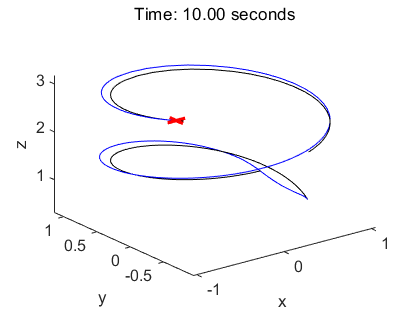

figure;
% 设置目标轨迹
plot3(out.simout.signals.values(:,13), out.simout.signals.values(:,14), out.simout.signals.values(:,15), '-k');
xlabel('x');
ylabel('y');
zlabel('z');
hold on;

% 设置实际轨迹的初始部分
h = plot3(out.simout.signals.values(1,1), out.simout.signals.values(1,2), out.simout.signals.values(1,3), 'b'); % 初始点

% 设置图形范围（根据实际数据调整）
xlim([min(out.simout.signals.values(:,1)) max(out.simout.signals.values(:,1))]);
ylim([min(out.simout.signals.values(:,2)) max(out.simout.signals.values(:,2))]);
zlim([min(out.simout.signals.values(:,3)) max(out.simout.signals.values(:,3))]);

% 创建一个十字架表示无人机
cross_size = 0.1;  % 十字架的大小，可以根据需要调整
% 使用 plot3 创建两条线来表示十字架
h_cross_x = plot3([out.simout.signals.values(1,1)-cross_size, out.simout.signals.values(1,1)+cross_size], ...
                  [out.simout.signals.values(1,2), out.simout.signals.values(1,2)], ...
                  [out.simout.signals.values(1,3), out.simout.signals.values(1,3)], 'r', 'LineWidth', 2);
              
h_cross_y = plot3([out.simout.signals.values(1,1), out.simout.signals.values(1,1)], ...
                  [out.simout.signals.values(1,2)-cross_size, out.simout.signals.values(1,2)+cross_size], ...
                  [out.simout.signals.values(1,3), out.simout.signals.values(1,3)], 'r', 'LineWidth', 2);

% 动态展示无人机轨迹和十字架
for i = 1:length(out.simout.time)
    % 更新实际轨迹（到第i个时刻）
    set(h, 'XData', out.simout.signals.values(1:i, 1));
    set(h, 'YData', out.simout.signals.values(1:i, 2));
    set(h, 'ZData', out.simout.signals.values(1:i, 3));
    
    % 更新十字架位置
    set(h_cross_x, 'XData', [out.simout.signals.values(i,1)-cross_size, out.simout.signals.values(i,1)+cross_size]);
    set(h_cross_x, 'YData', [out.simout.signals.values(i,2), out.simout.signals.values(i,2)]);
    set(h_cross_x, 'ZData', [out.simout.signals.values(i,3), out.simout.signals.values(i,3)]);
    
    set(h_cross_y, 'XData', [out.simout.signals.values(i,1), out.simout.signals.values(i,1)]);
    set(h_cross_y, 'YData', [out.simout.signals.values(i,2)-cross_size, out.simout.signals.values(i,2)+cross_size]);
    set(h_cross_y, 'ZData', [out.simout.signals.values(i,3), out.simout.signals.values(i,3)]);
    
    % 设置标题或其他动态信息
    title(sprintf('Time: %.2f seconds', out.simout.time(i)));
    
    % 暂停以展示动态效果（可调整暂停时间）
    pause(0.05); % 暂停0.05秒，根据需要调整
end

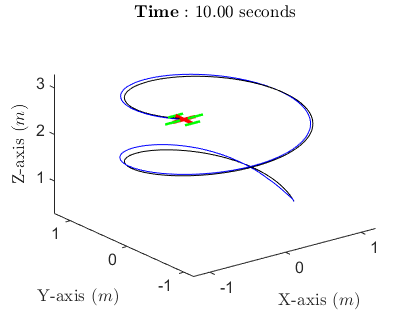


% 设置视频导出的相关参数
% video = VideoWriter('high_res_animation', 'MPEG-4');  % 输出为 MP4 格式
% video.Quality = 100;  % 设置视频质量（100 为最高质量）
% video.FrameRate = 30;  % 设置帧速率
% open(video);
% 设置图形的分辨率为 2 的倍数
figure;
% set(gcf, 'Position', [100, 100, 800, 600]); % 800x600 是 2 的倍数
% set(gcf, 'PaperPositionMode', 'auto'); 
% set(gcf, 'PaperSize', [8, 6]);
% set(gcf, 'Renderer', 'opengl');  % 适用于3D图形
% 设置目标轨迹
plot3(out.simout.signals.values(:,13), out.simout.signals.values(:,14), out.simout.signals.values(:,15), '-k');
xlabel('X-axis ($m$)', 'Interpreter', 'latex'); % X轴标签使用LaTeX
ylabel('Y-axis ($m$)', 'Interpreter', 'latex'); % Y轴标签使用LaTeX
zlabel('Z-axis ($m$)', 'Interpreter', 'latex'); % Z轴标签使用LaTeX
hold on;

% 设置实际轨迹的初始部分
h = plot3(out.simout.signals.values(1,1), out.simout.signals.values(1,2), out.simout.signals.values(1,3), 'b'); % 初始点

% 设置图形范围（根据实际数据调整）
xlim([min(out.simout.signals.values(:,1))-0.2 max(out.simout.signals.values(:,1))+0.2]);
ylim([min(out.simout.signals.values(:,2))-0.2 max(out.simout.signals.values(:,2))+0.2]);
zlim([min(out.simout.signals.values(:,3)) max(out.simout.signals.values(:,3))+0.1]);

% 创建一个十字架表示无人机
cross_size = 0.15;  % 十字架的大小
h_cross_x = plot3([out.simout.signals.values(1,1)-cross_size, out.simout.signals.values(1,1)+cross_size], ...
                  [out.simout.signals.values(1,2), out.simout.signals.values(1,2)], ...
                  [out.simout.signals.values(1,3), out.simout.signals.values(1,3)], 'r', 'LineWidth', 2);
h_cross_y = plot3([out.simout.signals.values(1,1), out.simout.signals.values(1,1)], ...
                  [out.simout.signals.values(1,2)-cross_size, out.simout.signals.values(1,2)+cross_size], ...
                  [out.simout.signals.values(1,3), out.simout.signals.values(1,3)], 'r', 'LineWidth', 2);

% 小十字架（旋翼）的位置和方向初始化
rotor_size = 0.1;  % 旋翼十字架的大小
h_rotor = gobjects(4,1);  % 用于存储四个旋翼的句柄

% 定义四个旋翼的初始位置（在主十字架的四个端点）
rotor_offsets = [cross_size, 0, 0;  % 右侧
                 -cross_size, 0, 0;  % 左侧
                 0, cross_size, 0;  % 上方
                 0, -cross_size, 0];  % 下方

% 绘制四个旋翼的初始位置
for j = 1:4
    h_rotor(j) = plot3([out.simout.signals.values(1,1)-rotor_size, out.simout.signals.values(1,1)+rotor_size], ...
                       [out.simout.signals.values(1,2)+rotor_offsets(j,2), out.simout.signals.values(1,2)+rotor_offsets(j,2)], ...
                       [out.simout.signals.values(1,3)+rotor_offsets(j,3), out.simout.signals.values(1,3)+rotor_offsets(j,3)], 'g', 'LineWidth', 1.5);
end

% 动态展示无人机轨迹、十字架和旋翼
for i = 1:length(out.simout.time)
    % 更新实际轨迹（到第i个时刻）
    set(h, 'XData', out.simout.signals.values(1:i, 1));
    set(h, 'YData', out.simout.signals.values(1:i, 2));
    set(h, 'ZData', out.simout.signals.values(1:i, 3));
    
    % 更新主十字架位置
    set(h_cross_x, 'XData', [out.simout.signals.values(i,1)-cross_size, out.simout.signals.values(i,1)+cross_size]);
    set(h_cross_x, 'YData', [out.simout.signals.values(i,2), out.simout.signals.values(i,2)]);
    set(h_cross_x, 'ZData', [out.simout.signals.values(i,3), out.simout.signals.values(i,3)]);
    
    set(h_cross_y, 'XData', [out.simout.signals.values(i,1), out.simout.signals.values(i,1)]);
    set(h_cross_y, 'YData', [out.simout.signals.values(i,2)-cross_size, out.simout.signals.values(i,2)+cross_size]);
    set(h_cross_y, 'ZData', [out.simout.signals.values(i,3), out.simout.signals.values(i,3)]);
    
    % 更新四个旋翼位置和旋转
    for j = 1:4
        % 更新旋翼位置
        x_offset = out.simout.signals.values(i, 1) + rotor_offsets(j, 1);
        y_offset = out.simout.signals.values(i, 2) + rotor_offsets(j, 2);
        z_offset = out.simout.signals.values(i, 3) + rotor_offsets(j, 3);
        
        % 计算旋转角度（模拟旋翼旋转，假设它们围绕Z轴旋转）
        angle = out.simout.time(i) * 360 * 2 * pi / 5;  % 5秒一圈旋转
        
        % 旋转矩阵（绕Z轴）
        R = [cos(angle), -sin(angle), 0; 
             sin(angle), cos(angle), 0; 
             0, 0, 1];
         
        % 旋转后的方向
        rotor_x_offset = rotor_size * R(1, 1);
        rotor_y_offset = rotor_size * R(2, 1);
        
        % 更新旋翼的两条线
        set(h_rotor(j), 'XData', [x_offset - rotor_x_offset, x_offset + rotor_x_offset]);
        set(h_rotor(j), 'YData', [y_offset - rotor_y_offset, y_offset + rotor_y_offset]);
        set(h_rotor(j), 'ZData', [z_offset, z_offset]);
    end
    
    % 设置标题或其他动态信息
    title(sprintf('$\\mathbf{Time:} \\ %.2f \\; \\mathrm{seconds}$', out.simout.time(i)), 'Interpreter', 'latex');    
    % 暂停以展示动态效果（可调整暂停时间）
    pause(0.01); % 暂停0.05秒，根据需要调整
   
end